# Multi-class Classification and Neural Network

## 1. Multi-class Classification

### 1.1 Dataset

There are 5000 training examples in MNIST`.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is unrolled into a 400-dimensional vector. 

This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

clear

load('MNIST.mat'); % Load MNIST file
data = [X y];
data = data(randperm(size(data, 1)), :); % Shuffle the data set

% Split the data set : 80% training set, 20% test set
TrainX = data(1:4000,1:400);
Trainy = data(1:4000,401);
TestX = data(4001:end,1:400);
Testy = data(4001:end,401);

fprintf('\nNumber of training examples is : %d & number of features is %d\n', size(TrainX,1), size(TrainX,2));


Number of training examples is : 4000 & number of features is 400


### 1.2 Visualizing the data

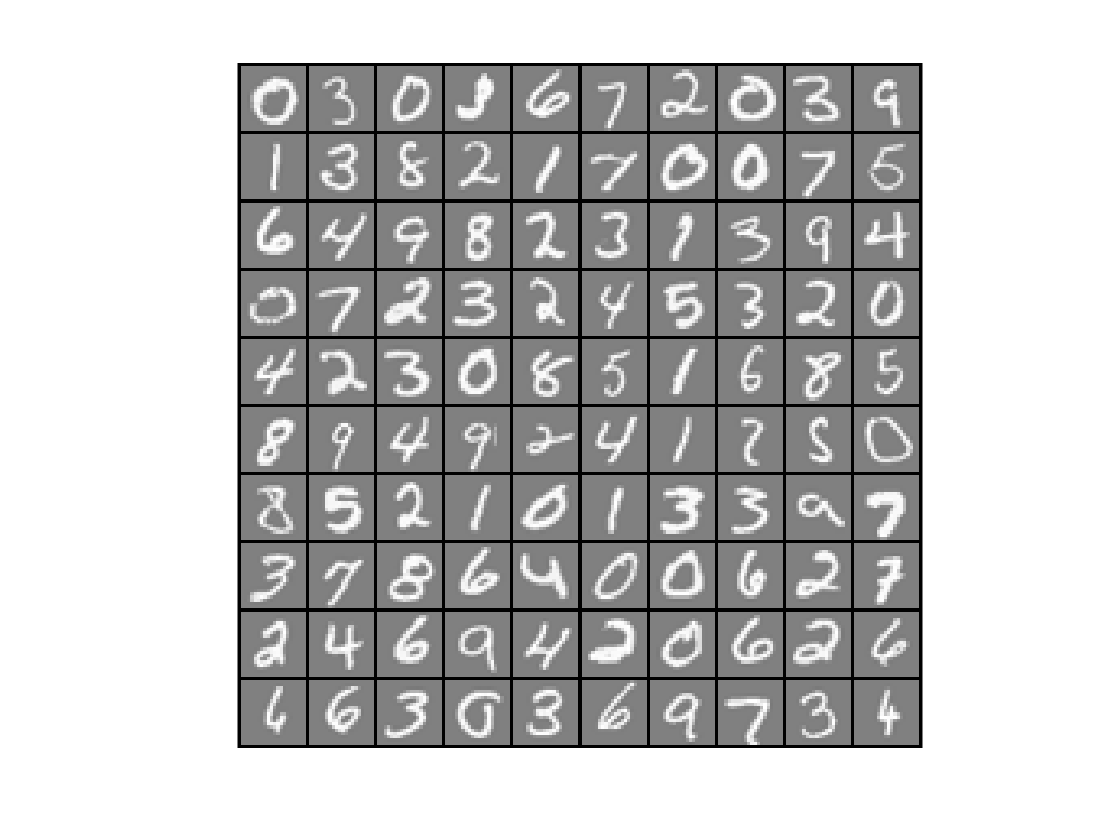

Trainm = size(TrainX, 1);

% Randomly select 100 data points to display
rand_indices = randperm(Trainm); % Random permutation
select = TrainX(rand_indices(1:100), :);
displayData(select);

### 1.3 One-vs-all classication

We use one-vs-all logistic regression models to build a multi-class classifier. Since there are 10 classes, we need to train 10 separate logistic regression classifiers. 

num_labels = 10; % 10 labels, from 1 to 10 
lambda = 0.1;
[all_theta] = oneVsAll(TrainX, Trainy, num_labels, lambda);

Iteration     1 | Cost: 2.768070e-01
Iteration     2 | Cost: 8.130227e-02
Iteration     3 | Cost: 5.581083e-02
Iteration     4 | Cost: 4.461499e-02
Iteration     5 | Cost: 4.184156e-02
Iteration     6 | Cost: 3.312331e-02
Iteration     7 | Cost: 3.004431e-02
Iteration     8 | Cost: 2.933813e-02
Iteration     9 | Cost: 2.639368e-02
Iteration    10 | Cost: 2.574111e-02
Iteration    11 | Cost: 2.443374e-02
Iteration    12 | Cost: 2.386844e-02
Iteration    13 | Cost: 2.309251e-02
Iteration    14 | Cost: 2.256434e-02
Iteration    15 | Cost: 2.188966e-02
Iteration    16 | Cost: 2.173841e-02
Iteration    17 | Cost: 2.151643e-02
Iteration    18 | Cost: 2.091207e-02
Iteration    19 | Cost: 2.079277e-02
Iteration    20 | Cost: 2.047197e-02
Iteration    21 | Cost: 1.946712e-02
Iteration    22 | Cost: 1.889963e-02
Iteration    23 | Cost: 1.847389e-02
Iteration    24 | Cost: 1.829850e-02
Iteration    25 | Cost: 1.805435e-02
Iteration    26 | Cost: 1.700980e-02
Iteration    27 | Cost: 1.612403e-02
I

### 1.4 One-vs-all prediction

After training our one-vs-all classifier, we can now use it to predict the digit contained in a given image. 

#### 1.4.1 Computing training set accuracy

predict = predictOneVsAll(all_theta, TrainX);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(predict == Trainy)) * 100);


Training Set Accuracy: 95.275000


#### 1.4.2 Computing test set accuracy

predict = predictOneVsAll(all_theta, TestX);
fprintf('\nTest Set Accuracy: %f\n', mean(double(predict == Testy)) * 100);


Test Set Accuracy: 91.500000


## 2. Neural Network

We will implement a neural network to recognize handwritten digits using the same training set as before. The neural network will be able to represent complex models that form non-linear hypotheses. 

### 2.1 Model representation

Our neural network as it's shown below, It has 3 layers- an input layer, a hidden layer and an output layer. The inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units.

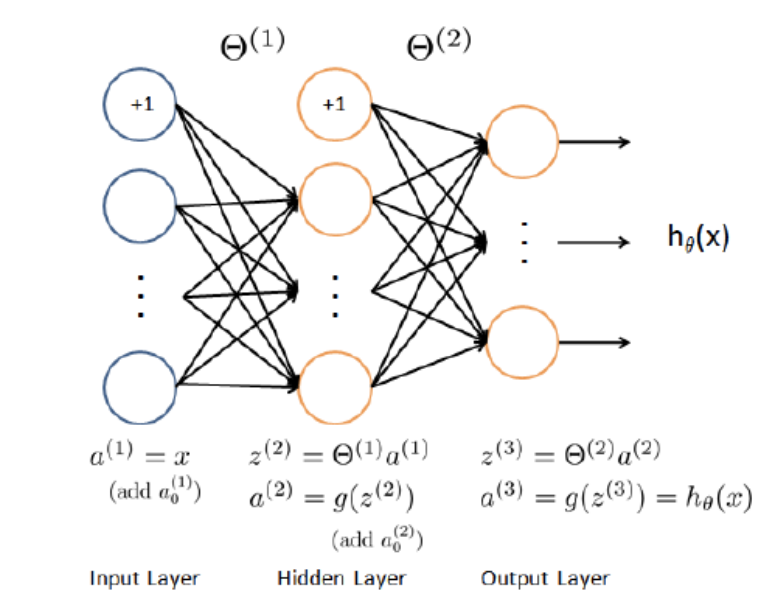

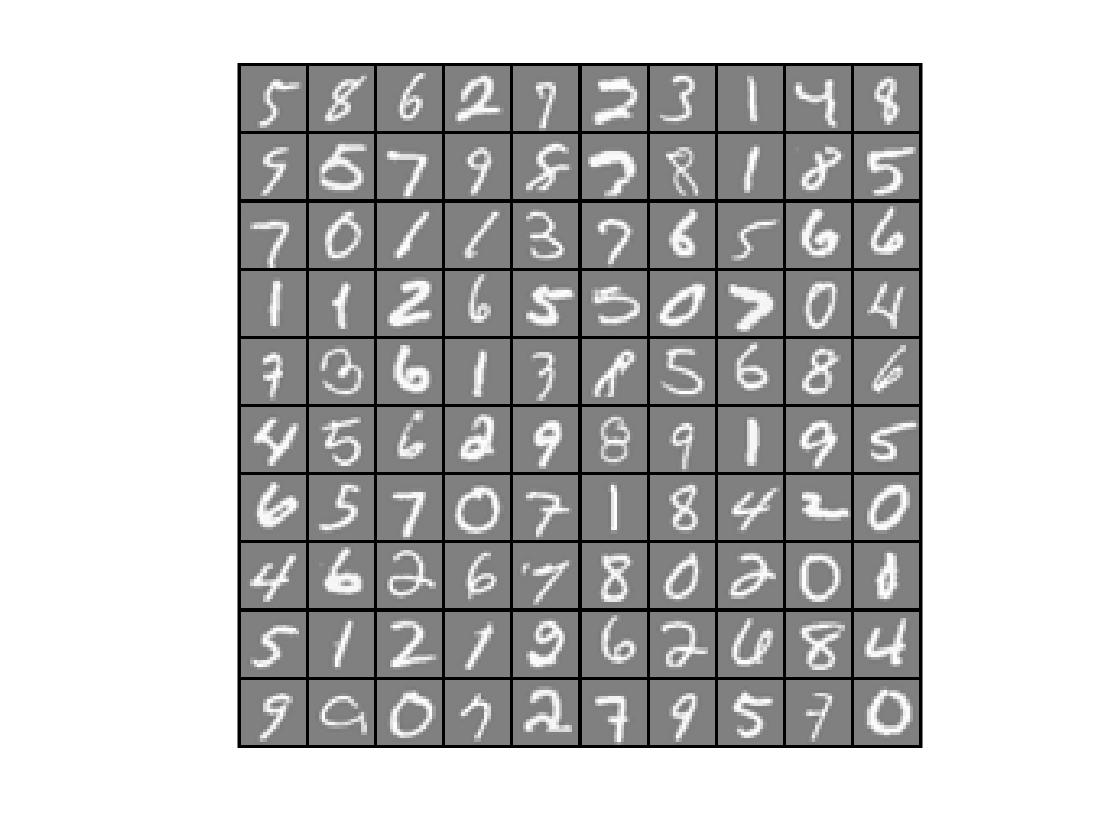

clear

load('MNIST.mat'); % Load MNIST file
data = [X y];
data = data(randperm(size(data, 1)), :); % Shuffle the data set
% Split the data set : 80% training set, 20% test set
TrainX = data(1:4000,1:400);
Trainy = data(1:4000,401);
TestX = data(4001:end,1:400);
Testy = data(4001:end,401);

Trainm = size(TrainX,1); % Number of examples in training set
Testm = size(TestX,1); % Number of examples in test set
input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10 (0 is mapped to 10)

% Randomly select 100 data points to display
rand_indices = randperm(size(TrainX, 1)); % Random permutation
select = rand_indices(1:100);
displayData(TrainX(select, :));

### 2.2 Regularized cost function

The cost function for neural networks with regularization is :


$$J(\theta) =
\frac{1}{m}\sum_{i=1}^m
\sum_{k=1}^K 
\left[ -y^{(i)}_k \log((h_{\theta}(x^{(i)})_k)- (1 -y^{(i)}_k) \log(1-(h_{\theta}(x^{(i)}))_k)  \right]
+\frac{\lambda}{2m} \left[\sum_{j=1}^{25} 
\sum_{k=1}^{400} {\left( \Theta_{j,k}^{(1)}\right)^2}+
\sum_{j=1}^{10} 
\sum_{k=1}^{25} {\left( \Theta_{j,k}^{(2)}\right)^2}\right]$$


### 2.3 Backpropagation

#### 2.3.1 Sigmoid derivate

The derivate for the sigmoid function can be computed as


$$g'(z)=\frac{d}{dz}g(z) = g(z)(1-g(z))$$


where


$$\mathrm{sigmoid}(z)=g(z)=\frac{1}{1+e^{-z}}$$


#### 2.3.2 Random initialization

When training neural networks, it is important to randomly initialize the parameters for symmetry breaking. One effective strategy for random initialization is to randomly select values for $\Theta^{(l)}$ uniformly in the range $[-\epsilon_{init},\epsilon_{init}]$. We use $\epsilon_{init} = 0.12$.

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

#### 2.3.3 Backpropagation

The intuition behind the backpropagation algorithm is as follows. Given a training example $(x^{(t)}, y^{(t)})$, we will first run a 'forward pass' to compute all the activations throughout the network, including the output value of the hypothesis $h_\Theta(x)$. Then, for each node $j$ in layer $l$, we would like to compute an 'error term' $\delta^{(l)}_j$ that measures how much that node was 'responsible' for any errors in our output.

For an output node, we can directly measure the difference between the network's activation and the true target value, and use that to define $\delta^{(3)}_j$ (since layer 3 is the output layer). For the hidden units, we compute $\delta^{(l)}_j$ based on a weighted average of the error terms of the nodes in layer $(l + 1)$.

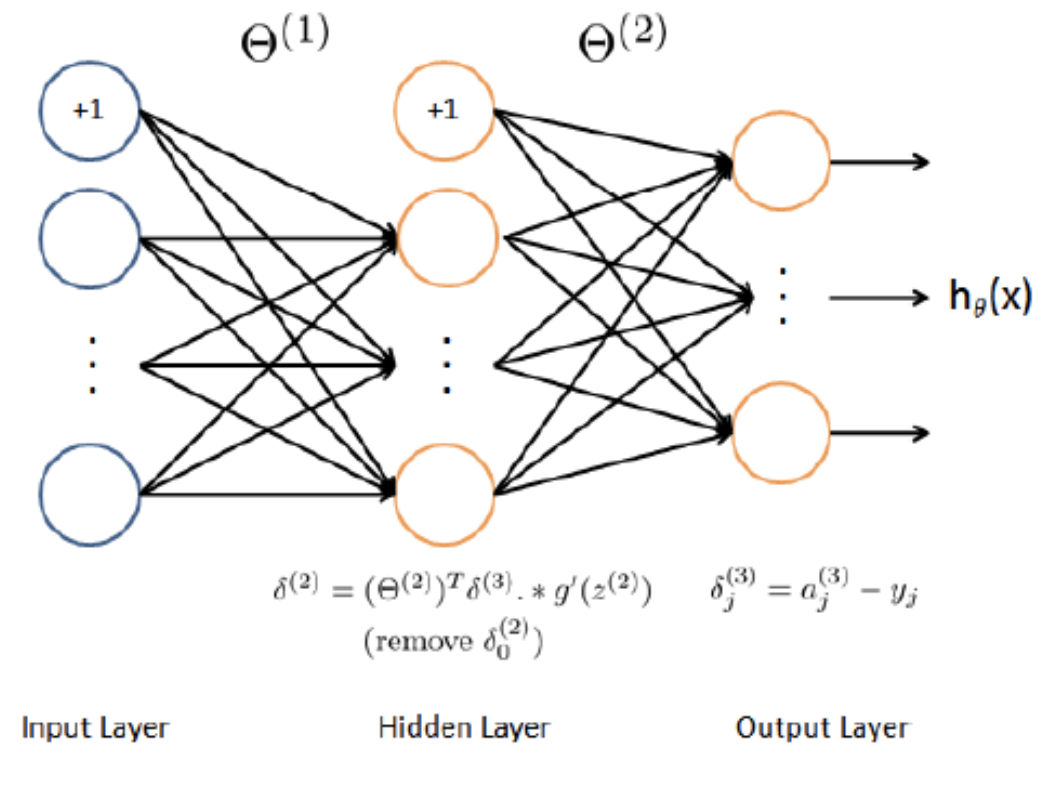

In detail, here is the backpropagation algorithm. 

- Set the input layer's values $(a^{(1)})$ to the $t$-th training example $x^{(t)}$. Perform a feedforward pass, computing the activations $(z^{(2)}, a^{(2)}, z^{(3)}, a^{(3)})$ for layers 2 and 3.

- For each output unit $k$ in layer 3 (the output layer), set $\delta^{(3)}_k = (a_k^{(3)}-y_k)$ where $y_k\in \{0, 1\}$ indicates whether the current training example belongs to class $k$ $(y_k = 1)$, or if it belongs to a different class $(y_k = 0)$.

- For the hidden layer $l = 2$, set $\delta^{(2)} = (\Theta^{(2)})^T \delta^{(3)}.*g'(z^{(2)})$

- Accumulate the gradient from this example using the following formula: $\Delta^{(l)} = \Delta^{(l)} + \delta^{(l+1)} (a^{(l)})^T$.

- Obtain the (unregularized) gradient for the neural network cost function by dividing the accumulated gradients by $\frac{1}{m}:$ $\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij}$

- Add regularization to the gradient :


$$\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} \text{  for  } j = 0,\\
\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} +\frac{\lambda}{m}\Theta^{(l)}_{ij} \text{  for  } j \geq 1$$


#### 2.3.4 Learning parameters using `fmincg`

We use a MATLAB built-in function called `fmincg i`nstead of taking gradient descent steps to find the optimal parameters.

options = optimset('MaxIter', 50);
lambda = 1;
% Create short-hand for the cost function
costFunction = @(p) neuralNetworkCostFunction(p, input_layer_size, hidden_layer_size, num_labels, TrainX, Trainy, lambda);
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);
% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));

### 2.4 Computing accuracy

% Training set accuracy
pred = predictNeuralNetwork(Theta1, Theta2, TrainX);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == Trainy)) * 100);
% Test set accuracy
pred = predictNeuralNetwork(Theta1, Theta2, TestX);
fprintf('\nTest Set Accuracy: %f\n', mean(double(pred == Testy)) * 100);

Iteration     1 | Cost: 3.302155e+00
Iteration     2 | Cost: 3.258978e+00
Iteration     3 | Cost: 3.215418e+00
Iteration     4 | Cost: 3.110598e+00
Iteration     5 | Cost: 2.960005e+00
Iteration     6 | Cost: 2.580039e+00
Iteration     7 | Cost: 2.389873e+00
Iteration     8 | Cost: 2.156498e+00
Iteration     9 | Cost: 1.976863e+00
Iteration    10 | Cost: 1.755101e+00
Iteration    11 | Cost: 1.571259e+00
Iteration    12 | Cost: 1.397567e+00
Iteration    13 | Cost: 1.280110e+00
Iteration    14 | Cost: 1.225921e+00
Iteration    15 | Cost: 1.130711e+00
Iteration    16 | Cost: 1.087208e+00
Iteration    17 | Cost: 1.054423e+00
Iteration    18 | Cost: 1.002721e+00
Iteration    19 | Cost: 9.406952e-01
Iteration    20 | Cost: 9.157846e-01
Iteration    21 | Cost: 8.947648e-01
Iteration    22 | Cost: 8.671386e-01
Iteration    23 | Cost: 8.072407e-01
Iteration    24 | Cost: 7.680633e-01
Iteration    25 | Cost: 7.235632e-01
Iteration    26 | Cost: 6.986662e-01
Iteration    27 | Cost: 6.912245e-01
I

### 2.5 Prediction test

random_example = randi(Testm); % Draw a random example in test set
% Predict
pred = predictNeuralNetwork(Theta1, Theta2, TestX(random_example,:));
fprintf('\nNeural Network Prediction: %d \nDigit Label: %d\n', mod(pred, 10), mod(Testy(random_example), 10));
% Display 
displayData(TestX(random_example, :));

### 2.6 Visualizing the hidden layer

It shows an image with 25 units, each corresponding to one hidden unit in the network.

% Visualize Weights 


Training Set Accuracy: 95.450000



Test Set Accuracy: 92.600000



Neural Network Prediction: 2 
Digit Label: 2


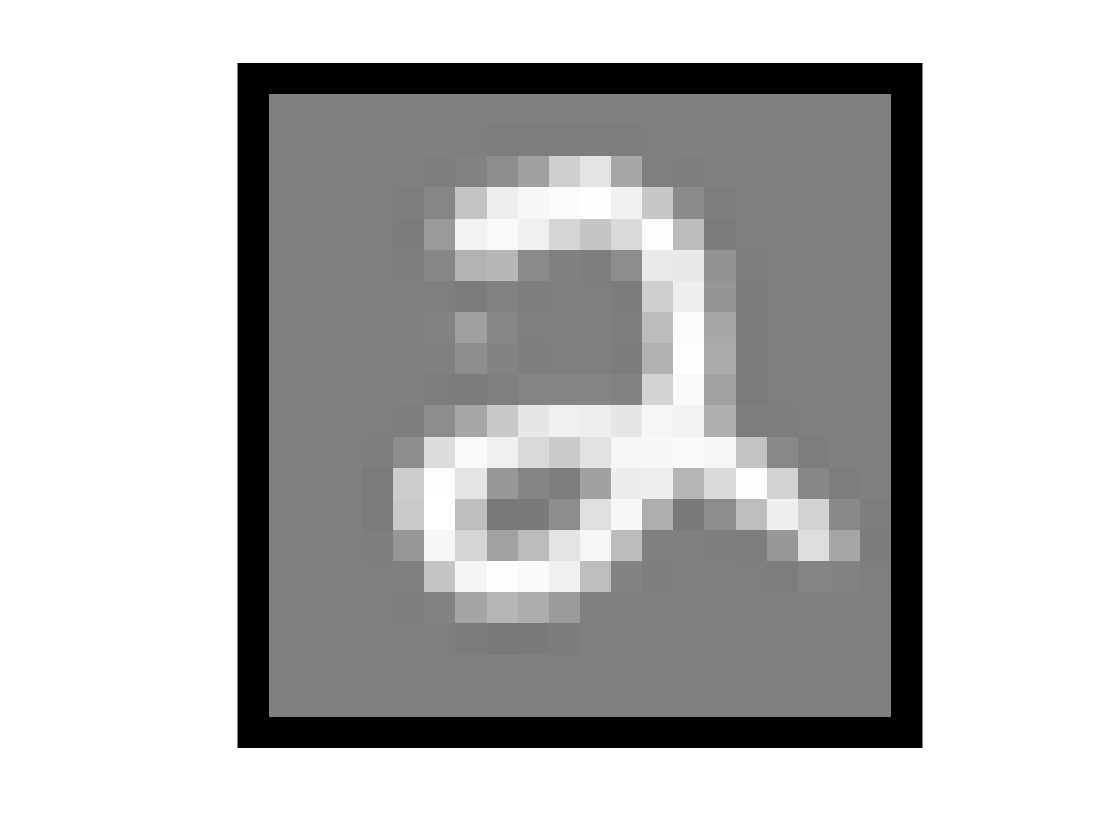

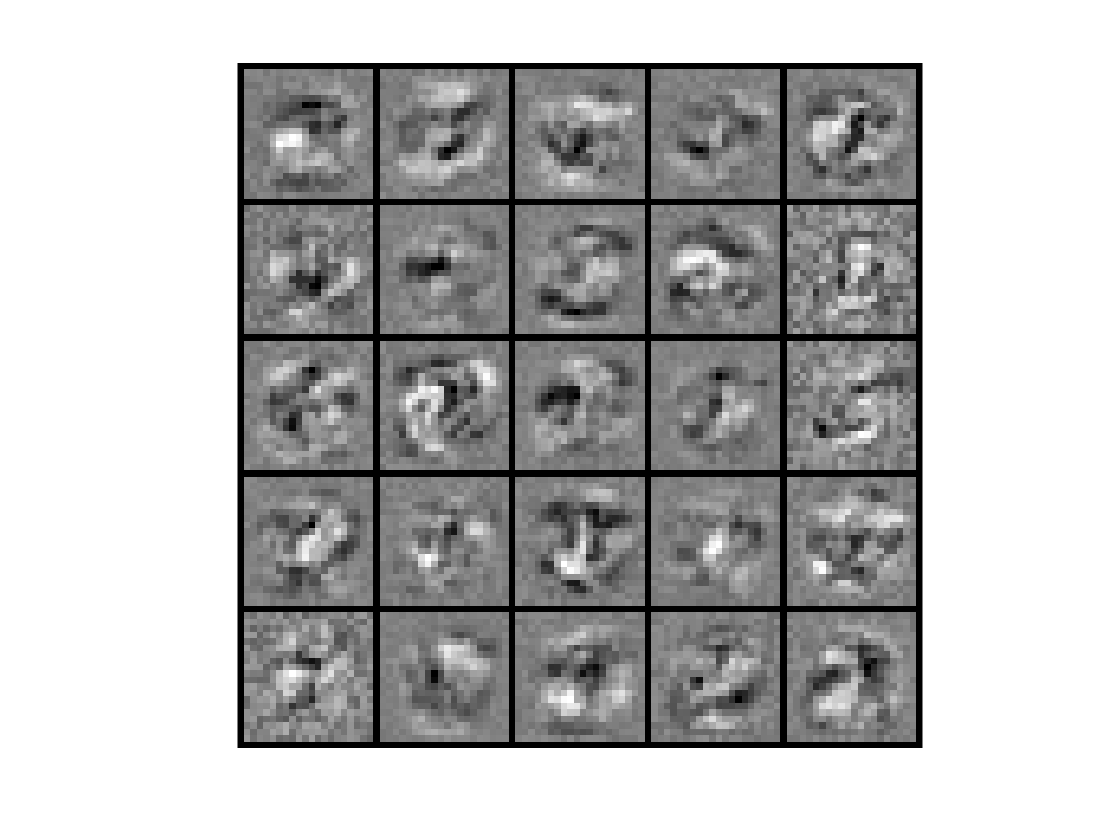

displayData(Theta1(:, 2:end));

We find that the hidden units corresponds roughly to detectors that look for strokes and other patterns in the input.